clear all
close all
warning off
load('resampdataset.mat')

con = q_u2(1:4*24)/max(q_u2(1:4*24));


%n = 96; %Number of sections
% n = 24;

t = 1:4*24; %Timeaxis. One time step equals 15min

dcon(1:length(t)*1/n) = mean(con(1:length(con)*1/n));
for i = 2:n
     dcon(length(t)*(i-1)/n+1:length(t)*i/n) = mean(con(length(con)*(i-1)/n+1:length(con)*i/n));
end

minVal = min(dcon), maxVal = max(dcon)

minVal = 0.0567

maxVal = 1

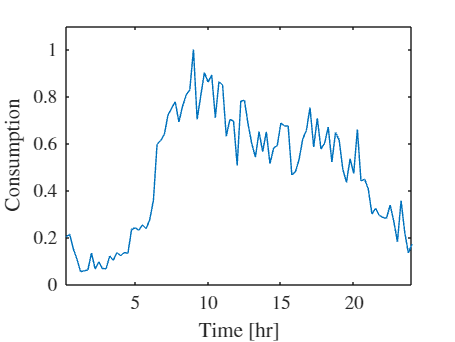


c = 1;

figure()
plot(t/4,c*con)
%hold on
%plot(t/4,c*dcon)
%hold off
xlim([min(t)/4 max(t)/4])
ylim([0 c*max(con)+0.1*max(con)])
xlabel('Time [hr]')
ylabel('Consumption')

%legend('Consumer Profile','Discretized Mean Consumption','interpreter','latex')

dcon = dcon(1:4:end);
%save('ConsumptionProfile','dcon')